# Hadamard Transmission Matrix

% Generate 2d hadamard basis
H=hadamard(2^7);
clear Hmn
for m=1:size(H,1)
    for n=1:size(H,2)
       Hmn{m,n}=(H(:,n)*H(m,:));
    end
end

addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\SPIFIandCHIRPTSims")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\ScatteringCZI\LaserPulse-master")
addpath("C:\Users\19709\Documents\MATLAB\Gabe_MATLAB\ScatteringCZI\LaserPulse-master\utilities")
clear variables

%% Grids

pdar        = 100;           % padding size before running forward model (to avoid edge artifacts)
ps          = 0.035*3;                % pixel size (x,y,z) in object space (micron)
lambda      = 0.5;                % central wavelength (micron)
NA          = 1.0;                  % numerical aperture of imaging and detection lens
n_imm       = 1.367;                 % refractive index of immersion media
k0=(2*pi)/lambda;
N           = 2^7;%2^9;                                  %120+2*pdar; %size(obj,1)+2*pdar;   % lateral pixel dimension of padded object
x           = ps*[-N/2:N/2-1];      % 1D padded axis in x
y=x;
dfx         = 1/(N*ps);             % Fourier spacing of padded axis
[X Y]=meshgrid(x,y);
fx          = dfx*[-N/2:N/2-1];     % 1D padded axis in fx
[fxx,fyy]   = meshgrid(fx,fx);      % 2D padded grid in fx/fy

fx          = ifftshift(fx);        % FFT shifting Fourier axes
fxx         = ifftshift(fxx);       % FFT shifting Fourier axes
fyy         = ifftshift(fyy);       % FFT shifting Fourier axes

% setting propagation kernels and pupil support
%prop_phs            = 1i*2*pi*sqrt((n_imm/lambda)^2-(fxx.^2+fyy.^2));
NA_crop             = (fxx.^2 + fyy.^2 > (NA/lambda)^2);
prop_crop           = (fxx.^2 + fyy.^2 > (n_imm/lambda)^2);

% Time grids for short pulse field

c=(3e8)*1e6*1e-15;                  % speed of light microns per fs
t0=50; % femtoseconds pulse dur.
t0a=t0*(sqrt(2)/(2*sqrt(2*log(2)))); % to ensure FWHM=t0
Nt=2^8;
t=2*t0/100*[-Nt/2:Nt/2-1];
dt=1/(Nt*(2*t0/100));
f=dt*[-Nt/2:Nt/2-1];

w0=(c/lambda)*2*pi;
%w0=w0*1e-15;                         % Converting to 1/fs units
%w=f*2*pi+w0;                            % Units of 1/fs shifting over to central freq
k=k0*n_imm;

## Build RI and Scattering potential

Last time did 10 scattering lengths now try 20

%% Building 3D RI material and scattering potential
l=.5;                 % Correlation length (um)
sigma=.01;            % standard deviation of RI
% Both match what is seen in actual tissue (see Min Xu's paper above)

nu=1;
RImodel='MW';

musMWred=@(l,nu,sig) sqrt(pi)*(1./l).*(sig^2).*(gamma(nu+.5)./abs(gamma(nu))).*(1./(nu-.5)).*(1-((1+4.*(k0.*l).^2).^(-nu-.5)).*(1+4.*((k0.*l).^2).*(nu+.5)));
mu_sMWa=@(l,nu,sig) 2*sqrt(pi)*(k0^2).*l.*(sig^2).*(gamma(nu+.5)./abs(gamma(nu))).*(1-(1+4.*(k0.*l).^2).^(-nu-.5));
mu_sMW=mu_sMWa(l,nu,sigma);%2*sqrt(pi)*(k^2)*l*(sigma^2)*(gamma(nu+.5)/abs(gamma(nu)))*(1-(1+4*(k*l)^2)^(-nu-.5));

if nu==.5
    mu_sMWr=(musMWred(l,.5-.00000001,sigma)+musMWred(l,.5+.00000001,sigma))/2;
else
%mu_sMWr=sqrt(pi)*(1/l)*(sigma^2)*(gamma(nu+.5)/abs(gamma(nu)))*(1/(nu-.5))*(1-((1+4*(k*l)^2)^(-nu-.5))*(1+4*((k*l)^2)*(nu+.5)));
mu_sMWr=musMWred(l,nu,sigma);
end

g_MW=1-mu_sMWr/mu_sMW;
g_MWa=@(l,nu,sig) 1-musMWred(l,nu,sig)./mu_sMWa(l,nu,sig);
disp(append('Scattering Length is:',num2str(1/mu_sMW),' ','microns'))

Scattering Length is:40.3346 microns


disp(append('Scattering Anisotropy is:',num2str(g_MWa(l,nu,sigma))))

Scattering Anisotropy is:0.97767



%% z Direction
L=4*(1/mu_sMW); %Thickness of media in microns
psz=1*ps;
Nz=round(L/psz)+1;
if mod(Nz,2)==0
    Nz=Nz+1;
end
%Nz=859; % needs to be odd????
z=psz*[-Nz/2:Nz/2-1];
zz=psz*[1:Nz];
fz          = dfx*[-Nz/2:Nz/2-1];  
disp(append('Thickness of RI is',' ',num2str(L*mu_sMW),' ','scattering lengths'))

Thickness of RI is 4 scattering lengths


prop_crop = (fxx.^2 + fyy.^2 > (n_imm/lambda)^2==0);
prop_phs= 1i*2*pi*sqrt((n_imm/lambda)^2-(fxx.^2+fyy.^2));
prop_phs=prop_phs.*prop_crop;
prop=@(z) exp(prop_phs*z);
PropField=@(U,z) ifft2(prop(z).*(fft2(U)));
[RI sdev avg]=RIGenerator3Single(RImodel,l,sigma,nu,x,y,z);
%disp(append('std is off by ','',num2str(-(sigma-sdev)/sigma*100),'%'))
RI=RI-avg;
%if abs(-(sigma-sdev)/sigma*100)>.2
RI=RI*(sigma/sdev); % Rescaling std

% Estimate time to run
tic;
evolR=zeros(N,N,'single'); %zeros(N,N,Nz,'single');
U_in=exp(1i*Hmn{5,50}*2*pi*k0).*ones(N,N,'single');
V=-(k0)^2*((RI+n_imm).^2-n_imm^2);
evolR=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,V,U_in);
toc;

Elapsed time is 3.030802 seconds.


% need to be able to loop hadamard basis easily

pp=0;
n=1:N;

NN=zeros(N^2,2);
NN(:,1)=reshape(repmat(n,N,1),[N^2,1]);
NN(:,2)=reshape(repmat(n',1,N),[N^2,1]);
for ii=1:(128^2)
    
    Hmnt(:,:,ii)=Hmn{NN(ii,1),NN(ii,2)};
end

clear Rlamb
fb=waitbar(0,append('Please wait... 0 of ',num2str(size(Hmnt,3))));
%evolR=zeros(N,N,Nz,'single'); %,'single'
Rlamb=zeros(N,N,size(Hmnt,3),'single');
U_in=ones(N,N);
for ii=1:size(Hmnt,3)
    clear V evolR evolB evolMS
    U_in=exp(1i*Hmnt(:,:,ii)*2*pi*k0).*ones(N,N,'single');
V=-(k0)^2*((RI+n_imm).^2-n_imm^2);
Rlamb(:,:,ii)=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,V,U_in);
%evolR=MLRv4(fxx,fyy,2*pi./Ki(ii),n_imm,ps,V,U_in);
% evolB=MLBv3(fxx,fyy,Lambda(ii),n_imm,ps,V,U_in);
% evolMS=MultiSlice(U_in,RI,Lambda(ii),ps,fxx,fyy,n_imm);
%Rlamb(:,:,ii)=evolR(:,:,end);
% Blamb(:,:,ii)=evolB(:,:,end);
% MSlamb(:,:,ii)=evolMS(:,:,end);
waitbar(ii/size(Hmnt,3),fb,append('Please wait... ',num2str(ii),' of ',num2str(size(Hmnt,3))));
end

close(fb)
%save("Pulsebroad20ls737points2_9_22.mat","Rlamb");
save("HadamardTransMatrix128v2.mat","Rlamb","RI",'-v7.3','-nocompression');
Tmatrix=reshape(Rlamb,[128^2 16384]);
[U S V]=svd(Tmatrix,'econ');

save("HadamardTransMatrix128.mat","Rlamb",'-v7.3','-nocompression');

Tmatrix=reshape(Rlamb,[128^2 16384]);

[U S V]=svd(Tmatrix,'econ');


$$S=\mu_s=2\sqrt{\pi}(\omega/c)^2l\langle(\delta m)^2\rangle\frac{\Gamma(\nu+.5)}{\Gamma(\nu)}\left(1-(1+4((\omega/c)l)^2)^{-\nu-.5}$$


delta=zeros(128,128);
delta(end/2,end/2)=10;
FocMode=pinv(Tmatrix)*delta(:);

Vp=-(k0)^2*((RI+n_imm).^2-n_imm^2);
MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,Vp,reshape(FocMode,[128 128]));

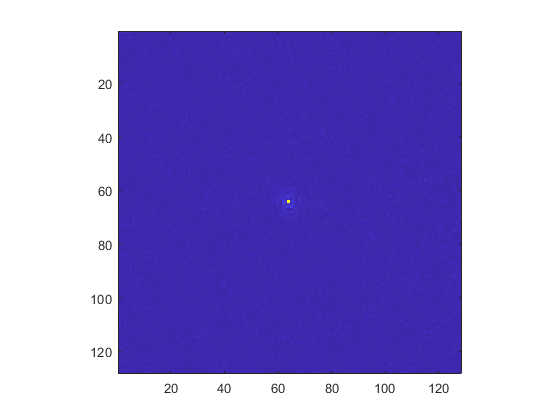

figure; imagesc(abs(reshape(Tmatrix*FocMode,[128 128])))
axis square

caxis([0 1])

CSU=im2double(imread('CSULogo.jpg'));
CSU=1-CSU(:,:,1);
CSU=imresize(CSU,[128 128]);

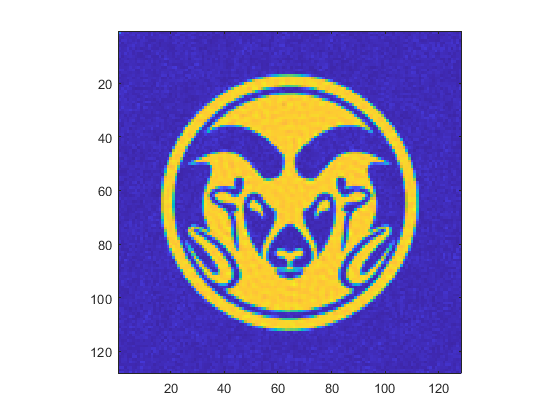

CSUMode=pinv(Tmatrix)*CSU(:);
figure; imagesc(abs(reshape(Tmatrix*CSUMode,[128 128])))
axis square

caxis([0 1])

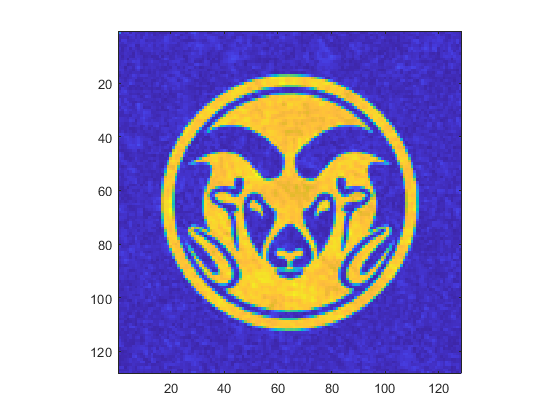

Hmntrs=reshape(Hmnt,[128^2 128^2]);
U_inCSU=reshape((Hmntrs*CSUMode),[128 128]);%exp(1i*reshape((Hmntrs*CSUMode),[128 128])*2*pi*k0).*ones(N,N,'single');
ECSU=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,Vp,U_inCSU);
figure; imagesc(abs(ECSU))
axis square

save('FieldInputtogetCAMtheRAM.mat','U_inCSU');

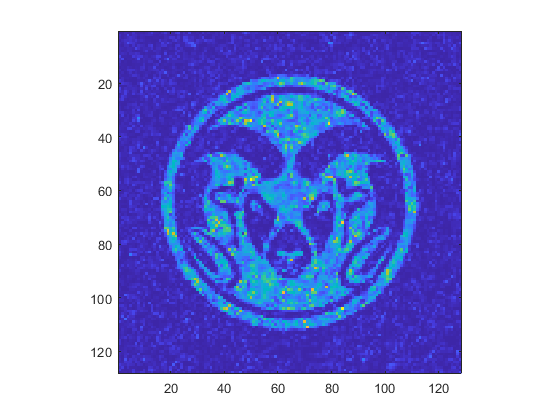

ECSU2=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,Vp,ones(N,N,'single').*exp(1i*angle(U_inCSU)));
figure; imagesc(abs(ECSU2).^2)
axis square

EvolCSU=ML2ndR(fxx,fyy,2*pi./k0,n_imm,ps,Vp,U_inCSU,'Vol');

IvolCSU=abs(EvolCSU);
IvolCSU(:,:,end)=IvolCSU(:,:,end)*5;

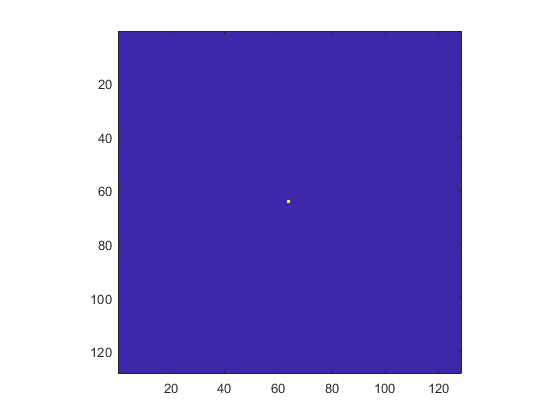

U_inFoc=reshape((Hmntrs*FocMode),[128 128]);%exp(1i*reshape((Hmntrs*CSUMode),[128 128])*2*pi*k0).*ones(N,N,'single');
EFoc=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,Vp,U_inFoc);
figure; imagesc(abs(EFoc))
axis square

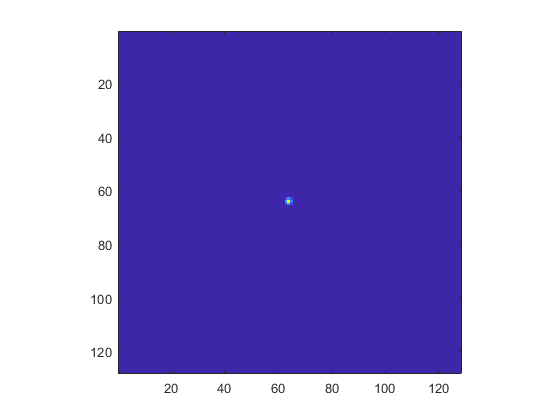

EFoc2=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,Vp,ones(N,N,'single').*exp(1i*angle(U_inFoc)));
figure; imagesc(abs(EFoc2).^2)
axis square

EvolFoc=ML2ndR(fxx,fyy,2*pi./k0,n_imm,ps,Vp,U_inFoc,'Vol');

EvolFoc2=ML2ndR(fxx,fyy,2*pi./k0,n_imm,ps,Vp,ones(N,N,'single').*exp(1i*angle(U_inFoc)),'Vol');

IvolFoc=abs(EvolFoc).^2;

save('HadamardTM1stTryResultsSVD.mat','FocMode','U','S','V','-v7.3','-nocompression')

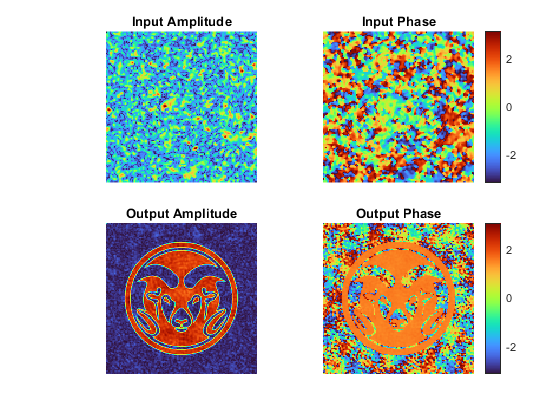

tiledlayout(2,2,'TileSpacing',"tight")
nexttile

imagesc(abs(U_inCSU))
title('Input Amplitude')
axis square
colormap Turbo
axis off
nexttile

imagesc(angle(U_inCSU))
title('Input Phase')
axis square
colormap Turbo
colorbar
axis off

nexttile

imagesc(abs(ECSU))
title('Output Amplitude')
axis square
colormap Turbo
axis off
nexttile

imagesc(angle(ECSU))
title('Output Phase')
axis square
colormap Turbo
colorbar

axis off

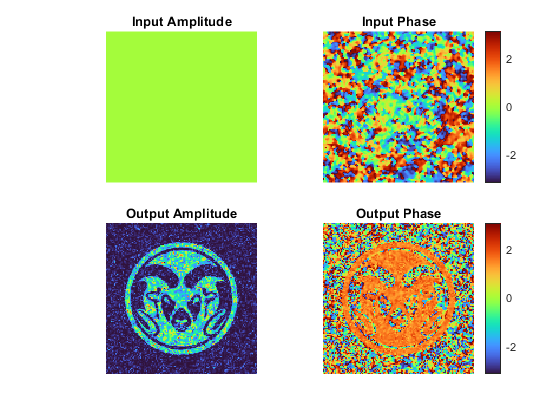

tiledlayout(2,2,'TileSpacing',"tight")
nexttile

imagesc(abs(ones(N,N,'single')))
title('Input Amplitude')
axis square
colormap Turbo
axis off
nexttile

imagesc(angle(U_inCSU))
title('Input Phase')
axis square
colormap Turbo
colorbar
axis off

nexttile

imagesc(abs(ECSU2).^2)
title('Output Amplitude')
axis square
colormap Turbo
axis off
nexttile

imagesc(angle(ECSU2))
title('Output Phase')
axis square
colormap Turbo
colorbar

axis off

PlaneIn=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,Vp,ones(N,N));

for ii=1:500
PlaneIn=MLRv4Out(fxx,fyy,2*pi./k0,n_imm,ps,Vp,ones(N,N).*exp(-1i*angle(PlaneIn)));
planeout(:,:,ii)=PlaneIn;
end

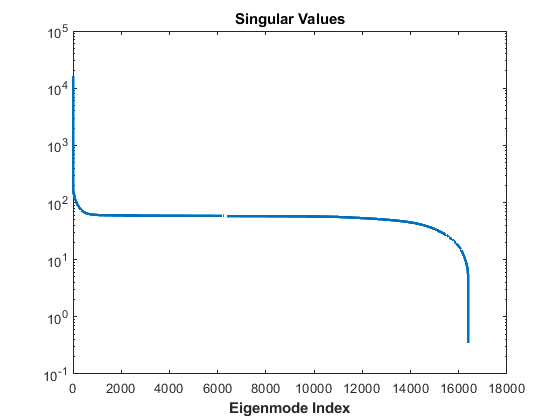

figure; semilogy((diag(S)),'LineWidth',2)
xlabel('Eigenmode Index','FontWeight',"bold")
%ylabel('Transmission','FontWeight',"bold")
title('Singular Values','FontWeight',"bold")

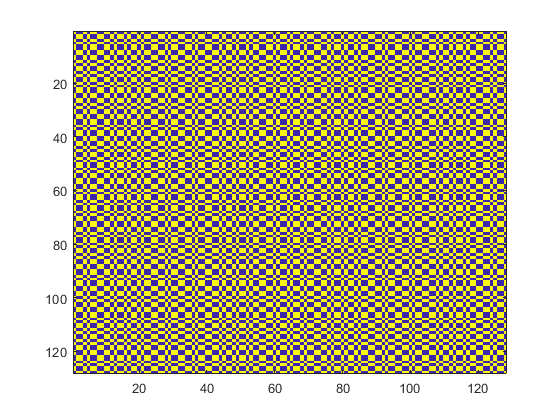

Hmntr=reshape(Hmnt,[128^2 16384]);
Hmntr*V(1,:)';
figure; imagesc(angle(reshape(ans,[128 128])))